***Wireless Communications EL-GY 6023***

Homework 1 - Tommy Azzino (ta1731)

Problem 4.a    

theta = pi/4;
phi = pi/4;
eul = [phi -theta 0];
rotmZYX = eul2rotm(eul,'ZYX');
xVec = [1 0 0]; % vector on the x-axis
newVec = rotmZYX*xVec.'

newVec =     0.5000
    0.5000
    0.7071


Problem 4.b

rotm = eul2rotm([pi/4 0 0],'ZYX');
rotm_n = eul2rotm([-pi/4 0 0],'ZYX');
disp(inv(rotm));

    0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000



disp(rotm_n); 

    0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000



% the two rotation matrixes are equal

Problem 4.c

rotm = eul2rotm([pi/4 pi/3 0],'ZYX');
rotm_n = eul2rotm([-pi/4 -pi/3 0],'ZYX');
disp(inv(rotm));

    0.3536    0.3536   -0.8660
   -0.7071    0.7071   -0.0000
    0.6124    0.6124    0.5000



disp(rotm_n);

    0.3536    0.7071   -0.6124
   -0.3536    0.7071    0.6124
    0.8660         0    0.5000



% the two rotation matrixes are different

Problem 9

% more points --> more accurate integral approximation
theta = linspace(-90,90,10000); % elevation angles
phi = linspace(-180,180,20000); % azimuth angles
% create radiation intesity of Problem 8
A = 10e-3;
U = (cos(deg2rad(theta)').^2 + cos(deg2rad(phi)).^2*0)*A;

% get the radiated power
Prad = get_radiated_power(U,theta,phi,180,360);
fprintf(1, 'Prad [dBm] is %f\n', pow2db(Prad*1e3));

Prad [dBm] is 19.230752



dir = get_directivity(U,Prad);
maxDir = max(dir,[],'all');
fprintf(1, 'Max Directivity [dBi] is %f\n', pow2db(maxDir));

Max Directivity [dBi] is 1.761347


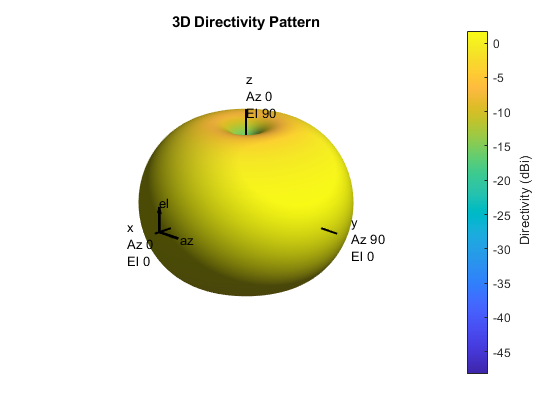

% same results as in Problem 8

% let's plot the directivity pattern of the antenna
phasePattern = zeros(size(dir));
ant = phased.CustomAntennaElement(...
    'AzimuthAngles', phi, 'ElevationAngles', theta, ...
    'MagnitudePattern', pow2db(dir), ...
    'PhasePattern', phasePattern);
fc = 28e9;
ant.pattern(fc);

function prad=get_radiated_power(U,theta,phi,theta_range,phi_range)
    theta_len = length(theta);
    phi_len = length(phi);
    U_times_cos = U'.*cos(deg2rad(theta));
    prad = sum(U_times_cos,'all')*deg2rad(theta_range)*deg2rad(phi_range)/(theta_len*phi_len);
end

function D=get_directivity(U, prad)
    D=U*4*pi/prad;
end